## Full System:


$$R_{growth}=  (\psi_g + \psi_d)\cdot\frac{(\eta_AA + 1)^{n_1} + \left(\frac{P_R}{\delta}\right)^{n_1}}{(\eta_B B_{ext} + 1)(\eta_AA+ 1)^{n_1}+ \left( \frac{P_R}{\delta} \right)^{n_1} } - \psi_d-\psi_C \cdot \frac{\eta_{I} I \cdot  \left(\frac{P_C}{\delta}\right)^{n_2}}{\eta_{I}I \cdot \left(\frac{P_C}{\delta}\right)^{n_2}+(\eta_AA +1)^{n_2}} $$



$$\frac{\mathrm{dy}}{\mathrm{dt}}=R_{\mathrm{growth}\;} \cdot y\left(1-y^{\upsilon } \right)$$


Parameter list:

x(1) = $\psi_g$

x(2) = $\psi_C$

x(3) = $P_C \cdot {\left(\eta_I \cdot I\right)}^{\frac{1}{n_2 }}$

x(4) = $\psi_d$

x(5) = $\eta_b$

x(6) = $P_r$

x(7) = $n_1$

x(8) = $n_2$

Loading data, normalization and converting to growth rate

clear all; close all;
addpath('./MatlabFuncs/')

xdata = [0, .2, .5, 1, 2, 5, 10, 20, 50, 100];

dataTable = readtable('Data\MeanSTD_Fitting.xlsx');

dataTable = table2array(dataTable);
y_data = dataTable(1:4, 2:end);
y_error = dataTable(5:8, 2:end);

% Converting y to growth rate
Y0 = 1/12; K = 1; t=96; nu=3.14;
r_data = revLogest(y_data, Y0, K, t, nu);
disp(r_data);

    0.0367    0.0378    0.0392    0.0393    0.0389    0.0385    0.0396    0.0396    0.0377    0.0360
   -0.0052   -0.0001    0.0032    0.0068    0.0099    0.0227    0.0298    0.0346    0.0374    0.0331
    0.0389    0.0374    0.0375    0.0380    0.0382    0.0365    0.0312    0.0183   -0.0104   -0.0205
   -0.0037    0.0021    0.0020    0.0049    0.0091    0.0138    0.0018   -0.0051   -0.0161   -0.0204



r_diff = r_data(1, :) - mean(r_data(1, :));
r_norm = r_data - r_diff;
disp(r_norm);

    0.0383    0.0383    0.0383    0.0383    0.0383    0.0383    0.0383    0.0383    0.0383    0.0383
   -0.0036    0.0005    0.0024    0.0058    0.0093    0.0225    0.0285    0.0332    0.0380    0.0354
    0.0405    0.0380    0.0367    0.0370    0.0377    0.0363    0.0299    0.0169   -0.0098   -0.0182
   -0.0021    0.0027    0.0012    0.0039    0.0085    0.0137    0.0006   -0.0065   -0.0154   -0.0181



disp(log(2) / mean(r_data(1, :)))

   18.0904



y_norm = endLogest(r_norm, Y0, 1, t, nu);
disp(y_norm);

    0.9926    0.9926    0.9926    0.9926    0.9926    0.9926    0.9926    0.9926    0.9926    0.9926
    0.0591    0.0874    0.1048    0.1459    0.2040    0.6548    0.8876    0.9677    0.9920    0.9827
    0.9961    0.9918    0.9881    0.9892    0.9910    0.9866    0.9207    0.4146    0.0326    0.0146
    0.0682    0.1079    0.0933    0.1213    0.1881    0.3072    0.0881    0.0448    0.0190    0.0147



Fitting the Blast and Casp9 arm together.

run('./MatlabFuncs/FuncGenerator.m');

options = optimoptions('lsqcurvefit','MaxFunctionEvaluations',100000, 'MaxIterations',40000); 
x0_both = [0.07, 0.1, 0.5, 0.1, 1, 2, 2, 1];

lowerLim = repelem(0, length(x0_both));
upperLim = repelem(inf, length(x0_both));
[x_both, renorm_both, residual_both] = lsqcurvefit(rate_func2,x0_both,xdata,[r_norm(3, :); r_norm(2, :)],lowerLim,upperLim,options);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


MSE_both = mean((residual_both).^2,2); % mean percentage error
disp(x_both);

    0.0382    0.0474    0.1719    0.0645    1.4268    2.1423    2.0358    1.1946



save('./Data/Param_Fit2', "x_both");

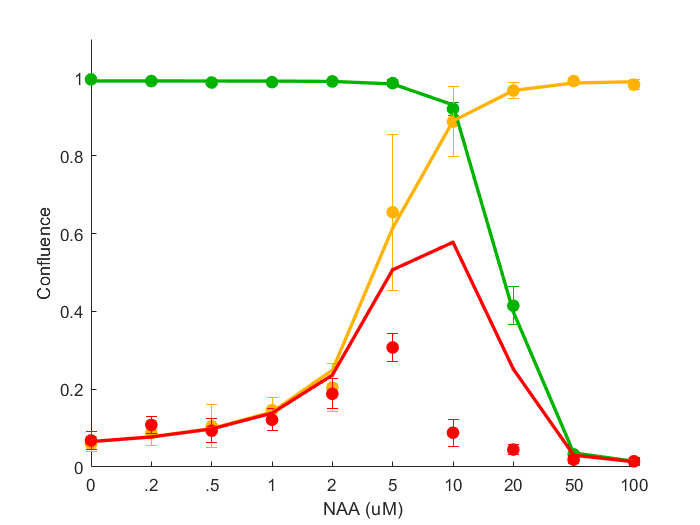

rpredict = [rate_func2(x_both, xdata); rate_comb(x_both, xdata)];
cpredict = endLogest(rpredict, Y0, 1, t, nu);

fig = figure(1); clf(fig);

hold on;

e1 = errorbar([1:length(xdata)],y_norm(3, :),y_error(3, :),'o','Color',[0,.7,0],'MarkerSize',7,...
    'MarkerEdgeColor',[0,.7,0],'MarkerFaceColor',[0,.7,0]);
e2 = errorbar([1:length(xdata)],y_norm(2, :),y_error(2, :),'o','Color',[1,.7,0],'MarkerSize',7,...
    'MarkerEdgeColor',[1,.7,0],'MarkerFaceColor',[1,.7,0]);
e3 = errorbar([1:length(xdata)],y_norm(4, :),y_error(4, :),'o','Color',[1,0,0],'MarkerSize',7,...
    'MarkerEdgeColor',[1,0,0],'MarkerFaceColor',[1,0,0]);

p1 = plot([1:length(xdata)],cpredict(1,:),'.-','Color',[0,.7,0],'MarkerFaceColor',[0,.7,0],'LineWidth',2);
p2 = plot([1:length(xdata)],cpredict(2,:),'.-','Color',[1,.7,0],'MarkerFaceColor',[1,.7,0],'LineWidth',2);
p3 = plot([1:length(xdata)],cpredict(3,:),'.-','Color',[1, 0,0],'MarkerFaceColor',[1, 0,0],'LineWidth',2);

ylim([0, 1.1])
xticklabels({'0','.2','.5','1','2','5','10', '20', '50', '100'});
xlabel('NAA (uM)');
ylabel({'Confluence'});
gca.FontSize = 24;

box off;

options = optimoptions('lsqcurvefit','MaxFunctionEvaluations',100000, 'MaxIterations',40000); 

lowerLim = repelem(0, length(x0_both));
upperLim = repelem(inf, length(x0_both));

[x_all, renorm_all, residual_all] = lsqcurvefit(rate_func3,x0_both,xdata,[r_norm(3, :); r_norm(2, :); r_norm(4, :)],lowerLim,upperLim,options);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


disp(x_all);

    0.0416    0.0590    0.1662    0.0728    1.2531    2.0000    1.5027    0.7418



save('./Data/Param_Fit3', "x_all");

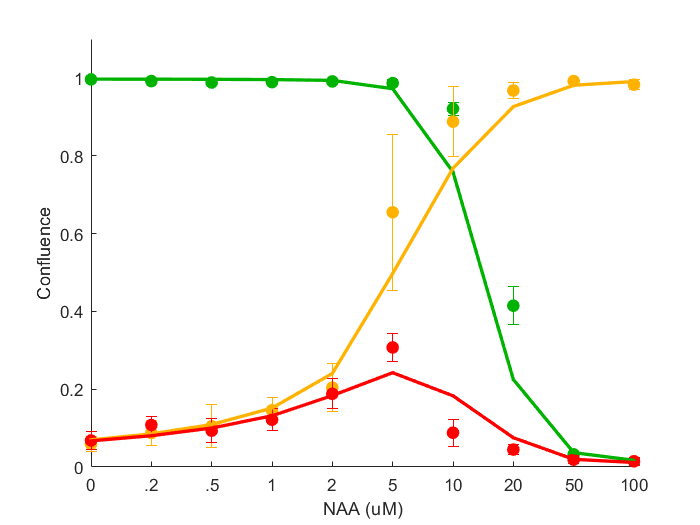

rpredict_all = rate_func3(x_all, xdata);
cpredict_all = endLogest(rpredict_all, Y0, 1, t, nu);

fig = figure(1); clf(fig);

hold on;

e1 = errorbar([1:length(xdata)],y_norm(3, :),y_error(3, :),'o','Color',[0,.7,0],'MarkerSize',7,...
    'MarkerEdgeColor',[0,.7,0],'MarkerFaceColor',[0,.7,0]);
e2 = errorbar([1:length(xdata)],y_norm(2, :),y_error(2, :),'o','Color',[1,.7,0],'MarkerSize',7,...
    'MarkerEdgeColor',[1,.7,0],'MarkerFaceColor',[1,.7,0]);
e3 = errorbar([1:length(xdata)],y_norm(4, :),y_error(4, :),'o','Color',[1,0,0],'MarkerSize',7,...
    'MarkerEdgeColor',[1,0,0],'MarkerFaceColor',[1,0,0]);

p1 = plot([1:length(xdata)],cpredict_all(1,:),'.-','Color',[0,.7,0],'MarkerFaceColor',[0,.7,0],'LineWidth',2);
p2 = plot([1:length(xdata)],cpredict_all(2,:),'.-','Color',[1,.7,0],'MarkerFaceColor',[1,.7,0],'LineWidth',2);
p3 = plot([1:length(xdata)],cpredict_all(3,:),'.-','Color',[1, 0,0],'MarkerFaceColor',[1, 0,0],'LineWidth',2);

ylim([0, 1.1])
xticklabels({'0','.2','.5','1','2','5','10', '20', '50', '100'});
xlabel('NAA (uM)');
ylabel({'Confluence'});
gca.FontSize = 24;

box off;